# Modified Euler Method

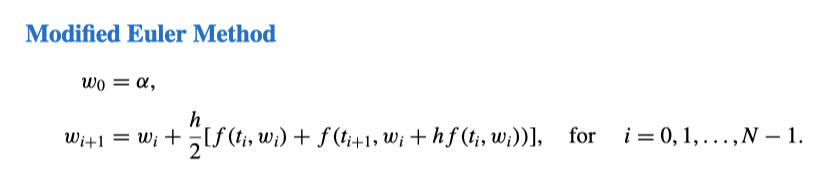

## Initialization

clc; clear; close all; %initialization

## Input the data

a=0; %input the left endpoint
b=2; %input the right endpoint
ya=0.5; %input the initial value on y(a)
N=10; %input the number of space
f=@(t,y) y-t^2+1;           %f



## Computation

h=(b-a)/N;
t=[];
w=[];



t(0 +1)=a;
w(0 +1)=ya;
for i=1:1:N
    fi=f(t(i-1 +1),w(i-1 +1));
    fi2=f(t(i-1 +1),w(i-1 +1+h*fi));
    T=fi+fi2;
    w(i +1)=w(i-1 +1)+h*T/2;
    t(i +1)=a+i*h;
end
plot(t,w);
disp(w(end));
